close all;
load out_noordergraaf_rideout_100s.mat

fontsize=15;
line_width=2;
color = {'#0072BD','#D95319','#EDB120','#7E2F8E','#77AC30','#4DBEEE','#A2142F'}; %list of colors from https://www.mathworks.com/help/matlab/creating_plots/specify-plot-colors.html
marker={'-','-+','-d','-.','-x','-o','-s','-*','-|','-^'};% marker symbols are given at https://www.mathworks.com/help/matlab/creating_plots/create-line-plot-with-markers.html

## Plotting preasures and flows

### Pressure curves for the Arms

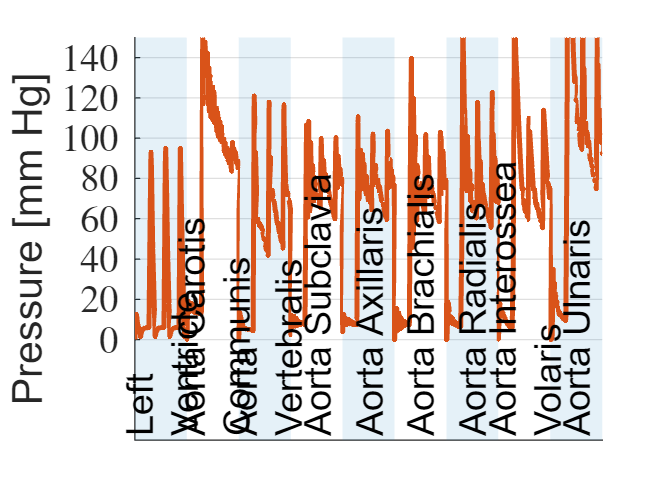

n1=1;%LV
n2=100;%ThA
n3=150;%AbA 
n4=100;% Iliac
n5=180;%FA
n6=250;%Poplitea
n7=250;%Tibialis Anterior
delta=4*1/sample_time;

Pressure=vertcat(out_sim.P_LV.data(n1:n1+delta),out_sim.P_Carot.data(n2:n2+delta),out_sim.P_Vert.data(n2:n2+delta),out_sim.P_SubC.data(n2:n2+delta),out_sim.P_Axi.data(n3:n3+delta),out_sim.P_Brach.data(n4:n4+delta),out_sim.P_Rad.data(n5:n5+delta),out_sim.P_Vola.data(n6:n6+delta),out_sim.P_TibPost.data(n7:n7+delta));

figure;
max_p=150;
time=(out_sim.P_LV.time(2)-out_sim.P_LV.time(1))*(0:length(Pressure)-1);
pos1=[0 0 time(delta) 130];
pos2=[2*time(delta) -50 time(delta) max_p];
pos3=[4*time(delta) -50 time(delta) max_p];
pos4=[6*time(delta) -50 time(delta) max_p];
pos5=[8*time(delta) -50 time(delta) max_p];

p=patch([0 pos1(3) pos1(3) 0],[-50 -50 max_p max_p],[0 0.4470 0.7410],'EdgeColor','none');hold on;%rectangle('Position',pos1,'FaceColor','#0072BD','EdgeColor','white');
set(p,'FaceAlpha',0.1);
p=patch([pos2(1) pos2(1)+pos2(3) pos2(1)+pos2(3) pos2(1)],[-50 -50 max_p max_p],[0 0.4470 0.7410],'EdgeColor','none');%rectangle('Position',pos2);
set(p,'FaceAlpha',0.1);
p=patch([pos3(1) pos3(1)+pos3(3) pos3(1)+pos3(3) pos3(1)],[-50 -50 max_p max_p],[0 0.4470 0.7410],'EdgeColor','none');%rectangle('Position',pos3);
set(p,'FaceAlpha',0.1);
p=patch([pos4(1) pos4(1)+pos4(3) pos4(1)+pos4(3) pos4(1)],[-50 -50 max_p max_p],[0 0.4470 0.7410],'EdgeColor','none');%rectangle('Position',pos4);
set(p,'FaceAlpha',0.1);
p=patch([pos5(1) pos5(1)+pos5(3) pos5(1)+pos5(3) pos5(1)],[-50 -50 max_p max_p],[0 0.4470 0.7410],'EdgeColor','none');%rectangle('Position',pos5);
set(p,'FaceAlpha',0.1);

plot(time,Pressure,'LineWidth',line_width,'Color','#D95319'); hold on; grid on;
ylabel('Pressure [mm Hg]');
% xlabel('time [s]');
axis([0 time(end) -50 max_p]);
set(gca,'FontSize',fontsize);
set(gca, 'XTick', [0]);
set(gca, 'XTickLabel', {' '}, 'TickLabelInterpreter', 'latex');
set(gca, 'YTick', [0 20 40 60 80 100 120 140]);
set(gca, 'YTickLabel', {'0','20','40','60','80','100','120','140'}, 'TickLabelInterpreter', 'latex');

%text
%text
y_txt=-48;

ht=text(pos1(1)+time(delta/2-25), y_txt,{'Left','Ventricle'},'FontSize',fontsize);
set(ht,'Rotation',90);
ht=text(pos1(1)+time(delta)+time(delta/2), y_txt,{'Aorta Carotis','Communis'},'FontSize',fontsize);
set(ht,'Rotation',90);
ht=text(pos2(1)+time(delta/2), y_txt,{'Aorta','Vertebralis'},'FontSize',fontsize);
set(ht,'Rotation',90);
ht=text(pos2(1)+time(delta)+time(delta/2), y_txt,{'Aorta Subclavia'},'FontSize',fontsize);
set(ht,'Rotation',90);
ht=text(pos3(1)+time(delta/2), y_txt,'Aorta Axillaris','FontSize',fontsize);
set(ht,'Rotation',90);
ht=text(pos3(1)+time(delta/2)+time(delta), y_txt,'Aorta Brachialis','FontSize',fontsize);
set(ht,'Rotation',90);
ht=text(pos4(1)+time(delta/2), y_txt,{'Aorta Radialis'},'FontSize',fontsize);
set(ht,'Rotation',90);
ht=text(pos4(1)+time(delta/2)+time(delta), y_txt,{'Aorta Interossea','Volaris'},'FontSize',fontsize);
set(ht,'Rotation',90);
ht=text(pos5(1)+time(delta/2), y_txt,{'Aorta Ulnaris'},'FontSize',fontsize);
set(ht,'Rotation',90);

### Pressure Curves for the Legs

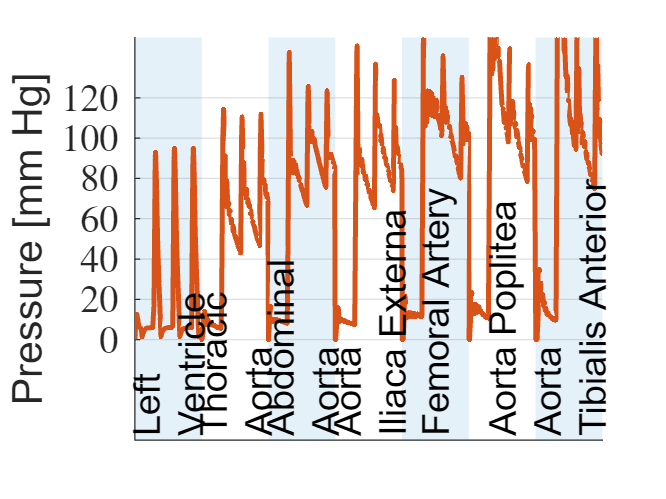

n1=1;%LV
n2=1;%ThA
n3=150;%AbA 
n4=100;% Iliac
n5=180;%FA
n6=250;%Poplitea
n7=250;%Tibialis Anterior
delta=4*1/sample_time;


%LAR-LVE
% exp_LAR_LVE=P_LAR.data(n5)*exp(-1/delta2*log(P_LAR.data(n5)/P_LVE.data(n6))*(0:delta2-1));
% exp_LVE_LSV=P_LVE.data(n6)*exp(-1/delta2*log(P_LVE.data(n6)/P_LSV.data(n7))*(0:delta2-1));
% exp_LSV_FEV=P_LSV.data(n7)*exp(-1/delta2*log(P_LSV.data(n7)/P_FEV.data(n8))*(0:delta2-1));
% exp_FEV_AVC=P_FEV.data(n8)*exp(-1/delta2*log(P_FEV.data(n8)/P_AVC.data(n9))*(0:delta2-1));

Pressure=vertcat(out_sim.P_LV.data(n1:n1+delta),out_sim.P_ThA.data(n2:n2+delta),out_sim.P_AbA.data(n3:n3+delta),out_sim.P_Iliac.data(n4:n4+delta),out_sim.P_FA.data(n5:n5+delta),out_sim.P_Po.data(n6:n6+delta),out_sim.P_TibPost.data(n7:n7+delta));

figure;
time=(out_sim.P_LV.time(2)-out_sim.P_LV.time(1))*(0:length(Pressure)-1);
pos1=[0 0 time(delta) 130];
pos2=[2*time(delta) -50 time(delta) max_p];
pos3=[4*time(delta) -50 time(delta) max_p];
pos4=[6*time(delta) -50 time(delta) max_p];
% pos5=[8*time(delta)-time(70)+3*time(delta) -50 time(delta)+time(delta) 130];
% pos6=[10*time(delta)-time(70)+4*time(delta) -50 time(delta) 120];

p=patch([0 pos1(3) pos1(3) 0],[-50 -50 max_p max_p],[0 0.4470 0.7410],'EdgeColor','none');hold on;%rectangle('Position',pos1,'FaceColor','#0072BD','EdgeColor','white');
set(p,'FaceAlpha',0.1);
p=patch([pos2(1) pos2(1)+pos2(3) pos2(1)+pos2(3) pos2(1)],[-50 -50 max_p max_p],[0 0.4470 0.7410],'EdgeColor','none');%rectangle('Position',pos2);
set(p,'FaceAlpha',0.1);
p=patch([pos3(1) pos3(1)+pos3(3) pos3(1)+pos3(3) pos3(1)],[-50 -50 max_p max_p],[0 0.4470 0.7410],'EdgeColor','none');%rectangle('Position',pos3);
set(p,'FaceAlpha',0.1);
p=patch([pos4(1) pos4(1)+pos4(3) pos4(1)+pos4(3) pos4(1)],[-50 -50 max_p max_p],[0 0.4470 0.7410],'EdgeColor','none');%rectangle('Position',pos4);
set(p,'FaceAlpha',0.1);
% p=patch([pos5(1) pos5(1)+pos5(3) pos5(1)+pos5(3) pos5(1)],[-50 -50 130 130],[0 0.4470 0.7410],'EdgeColor','none');%rectangle('Position',pos5);
% set(p,'FaceAlpha',0.1);
% p=patch([pos6(1) pos6(1)+pos6(3)+time(100) pos6(1)+pos6(3)+time(100) pos6(1)],[-50 -50 130 130],[0 0.4470 0.7410],'EdgeColor','none');%rectangle('Position',pos6);
% set(p,'FaceAlpha',0.1);


plot(time,Pressure,'LineWidth',line_width,'Color','#D95319'); hold on; grid on;
ylabel('Pressure [mm Hg]');
% xlabel('time [s]');
axis([0 time(end) -50 max_p]);
set(gca,'FontSize',fontsize);
set(gca, 'XTick', [0]);
set(gca, 'XTickLabel', {' '}, 'TickLabelInterpreter', 'latex');
set(gca, 'YTick', [0 20 40 60 80 100 120]);
set(gca, 'YTickLabel', {'0','20','40','60','80','100','120'}, 'TickLabelInterpreter', 'latex');

%text
y_txt=-48;
y_txt2=20;
ht=text(pos1(1)+time(delta/2-25), y_txt,{'Left','Ventricle'},'FontSize',fontsize);
set(ht,'Rotation',90);
ht=text(pos1(1)+time(delta)+time(delta/2), y_txt,{'Thoracic','Aorta'},'FontSize',fontsize);
set(ht,'Rotation',90);
ht=text(pos2(1)+time(delta/2), y_txt,{'Abdominal','Aorta'},'FontSize',fontsize);
set(ht,'Rotation',90);
ht=text(pos2(1)+time(delta)+time(delta/2), y_txt,{'Aorta', 'Iliaca Externa'},'FontSize',fontsize);
set(ht,'Rotation',90);
ht=text(pos3(1)+time(delta/2), y_txt,'Femoral Artery','FontSize',fontsize);
set(ht,'Rotation',90);
ht=text(pos3(1)+time(delta/2)+time(delta), y_txt,'Aorta Poplitea','FontSize',fontsize);
set(ht,'Rotation',90);
ht=text(pos4(1)+time(delta/2), y_txt,{'Aorta','Tibialis Anterior'},'FontSize',fontsize);
set(ht,'Rotation',90);

### Evaluating the center speed per circuit

Description: The speed is calculated per circuit evaluating the equation below

$v_{cse}=\frac{\Delta P_s r_{se}^2}{2\mu l_{se}}$     (1)         [1, below Eq. 4.9 pag. 54]

The circuits are given by the traveling path from the left ventricle in the heart to the capillary and back to the left ventricle heart. See for instance an example in Fig. 1 of a circuit through the spleen and the return to the left ventricle in heart. 

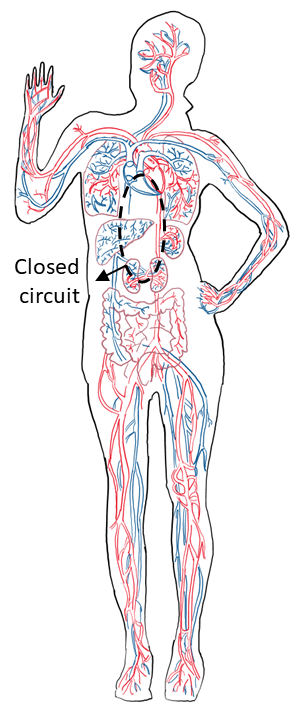

Fig. 1: Closed circuit representation in the HCS.

These traveling path can be visualized in the simulink file `Noordergraaf_Rideout.slx`. In total there are 11 circuits as listed below

%labeling the circuits in the HCS
circuits_tissues={...%upper body
                  'Head', ...% -> 1
                  'Volaris',...% -> 2
                  'Radialis',...% -> 3
                  'Ulnaris', ...% -> 4
                  ...%Center Body
                  'Thorax',...% -> 5
                  'Mesentrica Superior', ...% -> 6
                  'Mesenterica Inferior',...% -> 7
                  'Renalis',...% -> 8
                   ...%Lower Body
                   'Femoralis Profundis',...% -> 9
                   'Tibialis Anterior',...% -> 10
                   'Tibialis Posterior'};% -> 11

To evaluate the Eq. (1), we use the mean radius of the vessels segments in the circuit as for $r_{se}$ and the total length of the vessel segments as for $l_{se}$. As for the pressure $\Delta P_s$, we use the average pressure measured in left ventricle.

Reading the table of physiologic parameters

mu=3*10^(-2);%blood viscosity [3, pp. 128]
table=readtable('D:\code\Frankestein\Noordergraaf_Rideout\Parameters.xlsx');

%reading the radius and length per vessel segment
[rows,colums]=size(table);
vs_length=zeros(1,rows)';%vessel segment length in [m]
vs_radius=zeros(1,rows)';%vessel segment radius in [m]
for i=1:rows
    vs_length(table2array(table(i,2)))=table2array(table(i,7))*10^(-2);
    vs_radius(table2array(table(i,2)))=table2array(table(i,8))*10^(-2);
end

Finding the indexes per vessel segment in the table

vessel_segment={'Aorta Ascendens'};
vessel_idx_Asc=(table2array(table(find(string(table.VesselDescription)==vessel_segment),2)));
vessel_segment={'Arcus Aorta'};
vessel_idx_Arcus=(table2array(table(find(string(table.VesselDescription)==vessel_segment),2)));
vessel_segment={'Aorta Thoracalis'};
vessel_idx_Thor=(table2array(table(find(string(table.VesselDescription)==vessel_segment),2)));
vessel_segment={'Aorta Abdominalis'};
vessel_idx_Abd=(table2array(table(find(string(table.VesselDescription)==vessel_segment),2)));
vessel_segment={'A. Iliaca Communis'};
vessel_idx_Iliac_Comm=(table2array(table(find(string(table.VesselDescription)==vessel_segment),2)));
vessel_segment={'A. Iliaca Externa'};
vessel_idx_Iliac_Ext=(table2array(table(find(string(table.VesselDescription)==vessel_segment),2)));
vessel_segment={'A. Femoralis'};
vessel_idx_Fem=(table2array(table(find(string(table.VesselDescription)==vessel_segment),2)));
vessel_segment={'A. Poplitea'};
vessel_idx_Popl=(table2array(table(find(string(table.VesselDescription)==vessel_segment),2)));
vessel_segment={'A. Tibialis Posterior'};
vessel_idx_Popl=(table2array(table(find(string(table.VesselDescription)==vessel_segment),2)));
vessel_segment={'A. Profundis Femoris'};
vessel_idx_Prof_Fem=(table2array(table(find(string(table.VesselDescription)==vessel_segment),2)));
vessel_segment={'A. Tibialis Anterior'};
vessel_idx_Tib_Ant=(table2array(table(find(string(table.VesselDescription)==vessel_segment),2)));
vessel_segment={'A. Anonyma'};
vessel_idx_Ano=(table2array(table(find(string(table.VesselDescription)==vessel_segment),2)));
vessel_segment={'A. Renalis'};
vessel_idx_Ren=(table2array(table(find(string(table.VesselDescription)==vessel_segment),2)));
vessel_segment={'A. Mesenterica Sup.'};
vessel_idx_Mes_Sup=(table2array(table(find(string(table.VesselDescription)==vessel_segment),2)));
vessel_segment={'A. Mesenterica Inf.'};
vessel_idx_Mes_Inf=(table2array(table(find(string(table.VesselDescription)==vessel_segment),2)));
vessel_segment={'A. Coelica'};
vessel_idx_Coel=(table2array(table(find(string(table.VesselDescription)==vessel_segment),2)));
vessel_segment={'A. Hepatica'};
vessel_idx_Hep=(table2array(table(find(string(table.VesselDescription)==vessel_segment),2)));
vessel_segment={'A. Lienalis'};
vessel_idx_Lien=(table2array(table(find(string(table.VesselDescription)==vessel_segment),2)));
vessel_segment={'A. Gastrica Sinistra'};
vessel_idx_Gast=(table2array(table(find(string(table.VesselDescription)==vessel_segment),2)));
vessel_segment={'A. Carotis Comunis'};
vessel_idx_Car_Comm=(table2array(table(find(string(table.VesselDescription)==vessel_segment),2)));
vessel_segment={'A. Subclavia'};
vessel_idx_Subclavia=(table2array(table(find(string(table.VesselDescription)==vessel_segment),2)));
vessel_segment={'A. Axillaris'};
vessel_idx_Axil=(table2array(table(find(string(table.VesselDescription)==vessel_segment),2)));
vessel_segment={'A. Brachialis'};
vessel_idx_Brach=(table2array(table(find(string(table.VesselDescription)==vessel_segment),2)));
vessel_segment={'Aorta Ulnaris'};
vessel_idx_Uln=(table2array(table(find(string(table.VesselDescription)==vessel_segment),2)));
vessel_segment={'A. Vertebralis'};
vessel_idx_Vert=(table2array(table(find(string(table.VesselDescription)==vessel_segment),2)));
vessel_segment={'Aorta Radialis'};
vessel_idx_Rad=(table2array(table(find(string(table.VesselDescription)==vessel_segment),2)));
vessel_segment={'Aorta Volaris'};
vessel_idx_Vol=(table2array(table(find(string(table.VesselDescription)==vessel_segment),2)));
vessel_segment={'Aorta Carotis Communis d.'};
vessel_idx_Car_Comm_d=(table2array(table(find(string(table.VesselDescription)==vessel_segment),2)));
vessel_segment={'A. Tibialis Posterior'};
vessel_idx_Tib_Post=(table2array(table(find(string(table.VesselDescription)==vessel_segment),2)));

#### Calculating the radius, length, and speed in the center of the vessels' circuit

circuit_radius=zeros(1,11);%average radius per circuit
circuit_length=zeros(1,11);%total length per circuit
circuit_speed=zeros(1,11);%average speed per circuit
circuit_time_min=zeros(1,11);%average traveling time per circuit

Head: Asc $$\rightarrow$$Arcus $$\rightarrow$$Carotis Communis 

%mean radius
circuit_radius(1)=mean(vertcat(vs_radius(vessel_idx_Asc(1:end)),...
                                vs_radius(vessel_idx_Arcus(1)),...
                                vs_radius(vessel_idx_Car_Comm(1:end))));
%total length
circuit_length(1)=sum(vertcat(vs_length(vessel_idx_Asc(1:end)),...
                                vs_length(vessel_idx_Arcus(1)),...
                                vs_length(vessel_idx_Car_Comm(1:end))));
%Speed in the center
circuit_speed(1)=mean(out_sim.P_LV.Data)*(circuit_radius(1))^2/(2*mu*circuit_length(1));
%Traveling time
circuit_time_min(1)=circuit_length(1)/circuit_speed(1);

Volaris: Asc $$\rightarrow$$Arcus $$\rightarrow$$Subclavia $$\rightarrow$$ Axillaris $$\rightarrow$$Brachialis$$\rightarrow$$Ulnaris 1 $$\rightarrow$$Volaris 

%mean radius
circuit_radius(2)=mean(vertcat(vs_radius(vessel_idx_Asc(1:end)),...
                                vs_radius(vessel_idx_Arcus(1)),...
                                vs_radius(vessel_idx_Subclavia(1:end)),...
                                vs_radius(vessel_idx_Axil(1:end)),...
                                vs_radius(vessel_idx_Brach(1:end)),...
                                vs_radius(vessel_idx_Uln(1)),...
                                vs_radius(vessel_idx_Vol(1:end))));
%total length
circuit_length(2)=sum(vertcat(vs_length(vessel_idx_Asc(1:end)),...
                                vs_length(vessel_idx_Arcus(1)),...
                                vs_length(vessel_idx_Subclavia(1:end)),...
                                vs_length(vessel_idx_Axil(1:end)),...
                                vs_length(vessel_idx_Brach(1:end)),...
                                vs_length(vessel_idx_Uln(1)),...
                                vs_length(vessel_idx_Vol(1:end))));
%Speed in the center
circuit_speed(2)=mean(out_sim.P_LV.Data)*(circuit_radius(2))^2/(2*mu*circuit_length(2));
%Traveling time
circuit_time_min(2)=circuit_length(2)/circuit_speed(2);


Radialis: Asc $$\rightarrow$$Arcus $$\rightarrow$$Subclavia $$\rightarrow$$ Axillaris $$\rightarrow$$Brachialis$$\rightarrow$$Radialis 

%mean radius
circuit_radius(3)=mean(vertcat(vs_radius(vessel_idx_Asc(1:end)),...
                                vs_radius(vessel_idx_Arcus(1)),...
                                vs_radius(vessel_idx_Subclavia(1:end)),...
                                vs_radius(vessel_idx_Axil(1:end)),...
                                vs_radius(vessel_idx_Brach(1:end)),...
                                vs_radius(vessel_idx_Rad(1:end))));
%total length
circuit_length(3)=sum(vertcat(vs_length(vessel_idx_Asc(1:end)),...
                                vs_length(vessel_idx_Arcus(1)),...
                                vs_length(vessel_idx_Subclavia(1:end)),...
                                vs_length(vessel_idx_Axil(1:end)),...
                                vs_length(vessel_idx_Brach(1:end)),...
                                vs_length(vessel_idx_Rad(1:end))));
%Speed in the center
circuit_speed(3)=mean(out_sim.P_LV.Data)*(circuit_radius(3))^2/(2*mu*circuit_length(3));
%Traveling time
circuit_time_min(3)=circuit_length(3)/circuit_speed(3);


Ulnaris: Asc $$\rightarrow$$Arcus $$\rightarrow$$Subclavia $$\rightarrow$$ Axillaris $$\rightarrow$$Brachialis$$\rightarrow$$Ulnaris 

%mean radius
circuit_radius(4)=mean(vertcat(vs_radius(vessel_idx_Asc(1:end)),...
                                vs_radius(vessel_idx_Arcus(1)),...
                                vs_radius(vessel_idx_Subclavia(1:end)),...
                                vs_radius(vessel_idx_Axil(1:end)),...
                                vs_radius(vessel_idx_Brach(1:end)),...
                                vs_radius(vessel_idx_Uln(1:end))));
%total length
circuit_length(4)=sum(vertcat(vs_length(vessel_idx_Asc(1:end)),...
                                vs_length(vessel_idx_Arcus(1)),...
                                vs_length(vessel_idx_Subclavia(1:end)),...
                                vs_length(vessel_idx_Axil(1:end)),...
                                vs_length(vessel_idx_Brach(1:end)),...
                                vs_length(vessel_idx_Uln(1:end))));
%Speed in the center
circuit_speed(4)=mean(out_sim.P_LV.Data)*(circuit_radius(4))^2/(2*mu*circuit_length(4));
%Traveling time
circuit_time_min(4)=circuit_length(4)/circuit_speed(4);

Thorax: Asc $$\rightarrow$$Arcus $$\rightarrow$$Thorax $$\rightarrow$$ Coelica $$\rightarrow$$Lienalis 

%mean radius
circuit_radius(5)=mean(vertcat(vs_radius(vessel_idx_Asc(1:end)),...
                                 vs_radius(vessel_idx_Arcus(1:end)),...
                                 vs_radius(vessel_idx_Thor(1:end)),...
                                 vs_radius(vessel_idx_Coel(1:end)),...
                                 vs_radius(vessel_idx_Lien(1:end))));
%total length
circuit_length(5)=sum(vertcat(vs_length(vessel_idx_Asc(1:end)),...
                                 vs_length(vessel_idx_Arcus(1:end)),...
                                 vs_length(vessel_idx_Thor(1:end)),...
                                 vs_length(vessel_idx_Coel(1:end)),...
                                 vs_length(vessel_idx_Lien(1:end))));
%Speed in the center
circuit_speed(5)=mean(out_sim.P_LV.Data)*(circuit_radius(5))^2/(2*mu*circuit_length(5));
%Traveling time
circuit_time_min(5)=circuit_length(5)/circuit_speed(5);


Mesenterica Sup: Asc $$\rightarrow$$Arcus $$\rightarrow$$Thorax $$\rightarrow$$ Abdominalis $$\rightarrow$$Mesenterica Sup.

%mean radius
circuit_radius(6)=mean(vertcat(vs_radius(vessel_idx_Asc(1:end)),...
                                     vs_radius(vessel_idx_Arcus(1:end)),...
                                     vs_radius(vessel_idx_Thor(1:end)),...
                                     vs_radius(vessel_idx_Abd(1)),...
                                     vs_radius(vessel_idx_Mes_Sup(1:end))));
%total length
circuit_length(6)=sum(vertcat(vs_length(vessel_idx_Asc(1:end)),...
                                     vs_length(vessel_idx_Arcus(1:end)),...
                                     vs_length(vessel_idx_Thor(1:end)),...
                                     vs_length(vessel_idx_Abd(1)),...
                                     vs_length(vessel_idx_Mes_Sup(1:end))));
%Speed in the center
circuit_speed(6)=mean(out_sim.P_LV.Data)*(circuit_radius(6))^2/(2*mu*circuit_length(6));
%Traveling time
circuit_time_min(6)=circuit_length(6)/circuit_speed(6);


Mesenterica Inf: Asc $$\rightarrow$$Arcus $$\rightarrow$$Thorax $$\rightarrow$$ Abdominalis $$\rightarrow$$Mesenterica Inf.

%mean radius
circuit_radius(7)=mean(vertcat(vs_radius(vessel_idx_Asc(1:end)),...
                                     vs_radius(vessel_idx_Arcus(1:end)),...
                                     vs_radius(vessel_idx_Thor(1:end)),...
                                     vs_radius(vessel_idx_Abd(1:end)),...
                                     vs_radius(vessel_idx_Mes_Inf(1:end))));
%total length
circuit_length(7)=sum(vertcat(vs_length(vessel_idx_Asc(1:end)),...
                                     vs_length(vessel_idx_Arcus(1:end)),...
                                     vs_length(vessel_idx_Thor(1:end)),...
                                     vs_length(vessel_idx_Abd(1:end)),...
                                     vs_length(vessel_idx_Mes_Sup(1:end))));
%Speed in the center
circuit_speed(7)=mean(out_sim.P_LV.Data)*(circuit_radius(7))^2/(2*mu*circuit_length(7));
%Traveling time
circuit_time_min(7)=circuit_length(7)/circuit_speed(7);


Renalis: Asc $$\rightarrow$$Arcus $$\rightarrow$$Thorax $$\rightarrow$$ Abdominalis 1$$\rightarrow$$ Renalis

%mean radius
circuit_radius(8)=mean(vertcat(vs_radius(vessel_idx_Asc(1:end)),...
                               vs_radius(vessel_idx_Arcus(1:end)),...
                               vs_radius(vessel_idx_Thor(1:end)),...
                               vs_radius(vessel_idx_Abd(1)),...
                               vs_radius(vessel_idx_Ren(1:end))));
%total length
circuit_length(8)=sum(vertcat(vs_length(vessel_idx_Asc(1:end)),...
                                     vs_length(vessel_idx_Arcus(1:end)),...
                                     vs_length(vessel_idx_Thor(1:end)),...
                                     vs_length(vessel_idx_Abd(1:end)),...
                                     vs_length(vessel_idx_Mes_Sup(1:end))));
%Speed in the center
circuit_speed(8)=mean(out_sim.P_LV.Data)*(circuit_radius(8))^2/(2*mu*circuit_length(8));
%Traveling time
circuit_time_min(8)=circuit_length(8)/circuit_speed(8);


Profundis Femoris: Asc $$\rightarrow$$Arcus $$\rightarrow$$Thorax $$\rightarrow$$ Abdominalis $$\rightarrow$$Illiaca Comm. $$\rightarrow$$Iliaca Externa$$\rightarrow$$A. Femoralis 1$$\rightarrow$$Profundis Femoris

%mean radius
circuit_radius(9)=mean(vertcat(vs_radius(vessel_idx_Asc(1:end)),...
                                     vs_radius(vessel_idx_Arcus(1:end)),...
                                     vs_radius(vessel_idx_Thor(1:end)),...
                                     vs_radius(vessel_idx_Abd(1:end)),...
                                     vs_radius(vessel_idx_Iliac_Comm(1:end)),...
                                     vs_radius(vessel_idx_Iliac_Ext(1:end)),...
                                     vs_radius(vessel_idx_Fem(1)),...
                                     vs_radius(vessel_idx_Prof_Fem(1:end))));
%total length
circuit_length(9)=sum(vertcat(vs_length(vessel_idx_Asc(1:end)),...
                                     vs_length(vessel_idx_Arcus(1:end)),...
                                     vs_length(vessel_idx_Thor(1:end)),...
                                     vs_length(vessel_idx_Abd(1:end)),...
                                     vs_length(vessel_idx_Iliac_Comm(1:end)),...
                                     vs_length(vessel_idx_Iliac_Ext(1:end)),...
                                     vs_length(vessel_idx_Fem(1)),...
                                     vs_length(vessel_idx_Prof_Fem(1:end))));
%Speed in the center
circuit_speed(9)=mean(out_sim.P_LV.Data)*(circuit_radius(9))^2/(2*mu*circuit_length(9));
%Traveling time
circuit_time_min(9)=circuit_length(9)/circuit_speed(9);


Tibialis Anterior: Asc $$\rightarrow$$Arcus $$\rightarrow$$Thorax $$\rightarrow$$ Abdominalis $$\rightarrow$$Illiaca Comm. $$\rightarrow$$Iliaca Externa$$\rightarrow$$A. Femoralis $$\rightarrow$$Poplitea$$\rightarrow$$Tibialis Anterior

%mean radius
circuit_radius(10)=mean(vertcat(vs_radius(vessel_idx_Asc(1:end)),...
                                vs_radius(vessel_idx_Arcus(1:end)),...
                                vs_radius(vessel_idx_Thor(1:end)),...
                                vs_radius(vessel_idx_Abd(1:end)),...
                                vs_radius(vessel_idx_Iliac_Comm(1:end)),...
                                vs_radius(vessel_idx_Iliac_Ext(1:end)),...
                                vs_radius(vessel_idx_Fem(1:end)),...
                                vs_radius(vessel_idx_Popl(1:end)),...
                                vs_radius(vessel_idx_Tib_Ant(1:end))));
%total length
circuit_length(10)=sum(vertcat(vs_length(vessel_idx_Asc(1:end)),...
                                     vs_length(vessel_idx_Arcus(1:end)),...
                                     vs_length(vessel_idx_Thor(1:end)),...
                                     vs_length(vessel_idx_Abd(1:end)),...
                                     vs_length(vessel_idx_Iliac_Comm(1:end)),...
                                     vs_length(vessel_idx_Iliac_Ext(1:end)),...
                                     vs_length(vessel_idx_Fem(1:end)),...
                                     vs_length(vessel_idx_Popl(1:end)),...
                                     vs_length(vessel_idx_Tib_Ant(1:end))));
%Speed in the center
circuit_speed(10)=mean(out_sim.P_LV.Data)*(circuit_radius(10))^2/(2*mu*circuit_length(10));
%Traveling time
circuit_time_min(10)=circuit_length(10)/circuit_speed(10);


Tibialis Posterior: Asc $$\rightarrow$$Arcus $$\rightarrow$$Thorax $$\rightarrow$$ Abdominalis $$\rightarrow$$Illiaca Comm. $$\rightarrow$$Iliaca Externa$$\rightarrow$$A. Femoralis $$\rightarrow$$Poplitea$$\rightarrow$$Tibialis Posterior

%mean radius

%total length
circuit_length(11)=sum(vertcat(vs_length(vessel_idx_Asc(1:end)),...
                                     vs_length(vessel_idx_Arcus(1:end)),...
                                     vs_length(vessel_idx_Thor(1:end)),...
                                     vs_length(vessel_idx_Abd(1:end)),...
                                     vs_length(vessel_idx_Iliac_Comm(1:end)),...
                                     vs_length(vessel_idx_Iliac_Ext(1:end)),...
                                     vs_length(vessel_idx_Fem(1:end)),...
                                     vs_length(vessel_idx_Popl(1:end)),...
                                     vs_length(vessel_idx_Tib_Post(1:end))));

circuit_radius(11)=mean(vertcat(vs_radius(vessel_idx_Asc(1:end)),...
                                vs_radius(vessel_idx_Arcus(1:end)),...
                                vs_radius(vessel_idx_Thor(1:end)),...
                                vs_radius(vessel_idx_Abd(1:end)),...
                                vs_radius(vessel_idx_Iliac_Comm(1:end)),...
                                vs_radius(vessel_idx_Iliac_Ext(1:end)),...
                                vs_radius(vessel_idx_Fem(1:end)),...
                                vs_radius(vessel_idx_Popl(1:end)),...
                                vs_radius(vessel_idx_Tib_Post(1:end))));

%Speed in the center
circuit_speed(11)=mean(out_sim.P_LV.Data)*(circuit_radius(11))^2/(2*mu*circuit_length(11));
%Traveling time
circuit_time_min(11)=circuit_length(11)/circuit_speed(11);

Adjusting the circuit time, to consider the travel back through the veins

circuit_time_min=2*circuit_time_min;


#### Calculating the mean and minimum traveling time per circuit with the BVS data [4]

load BVS_training_data.mat
circuit_time_mean=[mean(delay_Head) mean(delay_Shoulders) mean(delay_UpperArms) mean(delay_Hands) ... %upper body
          mean(delay_Thorax) mean(delay_Liver) mean(delay_Spleen) mean(delay_Kidneys) ... %center body
          mean(delay_Pelvis) mean(delay_Knees) mean(delay_Feet)];

circuit_time_min=[min(delay_Head) min(delay_Shoulders) min(delay_UpperArms) min(delay_Hands) ... %upper body
          min(delay_Thorax) min(delay_Liver) min(delay_Spleen) min(delay_Kidneys) ... %center body
          min(delay_Pelvis) min(delay_Knees) min(delay_Feet)];

#### Plotting vessels' length and speed per circuit

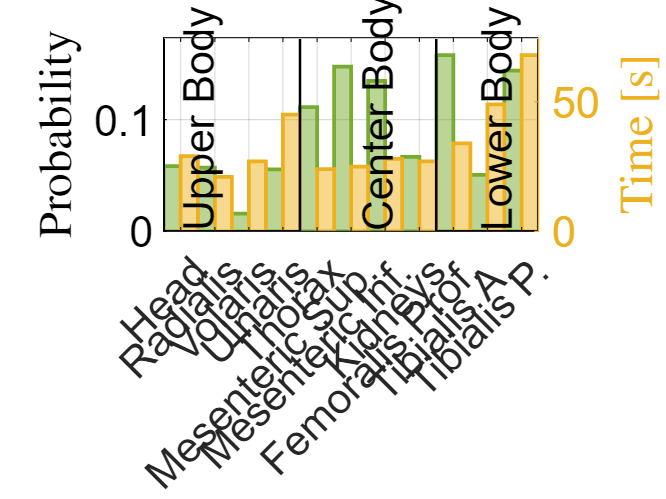

fontsize=17;
font2=17;
y_lim=0.3;
width=0.5;

figure;

%probability bars
p=bar((1:2:2*length(circuit_length)),prob_circuit,width,'LineWidth',1.5,'LineStyle','-','FaceColor','#77AC30','EdgeColor','#77AC30'); hold off
set(p,'FaceAlpha',0.5);
ylabel('Probability','Interpreter','latex');
axis([0.5 2*length(circuit_length)+1 0 1.1*max(prob_circuit)]);
set(gca,'FontSize',fontsize,'YColor','#77AC30');

yyaxis right
%traveling time bars
p=bar(2:2:2*length(circuit_length),circuit_time_min,width,'LineWidth',1.5,'LineStyle','-','FaceColor','#EDB120','EdgeColor','#EDB120'); hold on
set(p,'FaceAlpha',0.5);
ylabel('Time [s]','Interpreter','latex');
set(gca,'FontSize',fontsize,'YColor','#EDB120');

% set(gca, 'XTick', [1.5:2:2*length(circuit_length)]);
% set(gca, 'XTickLabel', {'Head','Radialis','Volaris','Ulnaris',...
%     'Thorax','Mesenteric Sup.','Mesenteric Inf.','Kidneys',...
%     'Femoralis Prof.','Tibialis A.','Tibialis P.'});
xticks(1.5:2:2*length(circuit_length))
xticklabels({'Head','Radialis','Volaris','Ulnaris',...
    'Thorax','Mesenteric Sup.','Mesenteric Inf.','Kidneys',...
    'Femoralis Prof.','Tibialis A.','Tibialis P.'})
xtickangle(45);
grid on;

%text
y_txt=0.15;
ht=text(2.5, y_txt,{'Upper Body'},'FontSize',font2);
set(ht,'Rotation',90);
ht=text(13, y_txt,{'Center Body'},'FontSize',font2);
set(ht,'Rotation',90);
ht=text(20, y_txt,{'Lower Body'},'FontSize',font2);
set(ht,'Rotation',90);

%patchs
%Upper body
p=patch([0.5 2*4+0.5 2*4+0.5 0.5],[0 0 1.1*max(circuit_time_min) 1.1*max(circuit_time_min)],[0.3010 0.7450 0.9330],"EdgeColor",'black','LineWidth',1);hold on;
set(p,'FaceAlpha',0);
%Lower body
p=patch([16.5 22.5 22.5 16.5],[0 0 1.1*max(circuit_time_min) 1.1*max(circuit_time_min)],[0.3010 0.7450 0.9330],"EdgeColor",'black','LineWidth',1);
set(p,'FaceAlpha',0);

axis([0.5 2*length(prob_circuit)+0.5 0 1.1*max(circuit_time_min)]);

### Plotting the PDF for the traveling time along a circuit


$$h_{c_ic_i}(\tau)=\frac{l_{c_i}}{2v_c\tau^2\sqrt{1-\frac{T_{c_i}}{\tau}}}u\left(\tau-T_{c_i}\right)$$


figure;
time=0:sample_time:4*max(circuit_time_min);
jump=1;
k=1;
for i=2:jump:4
    t1=find(time>=circuit_length(i)/circuit_speed(i),1);
    plot(time,...
         horzcat(zeros(1,t1-1),...
         circuit_length(i)./(2*circuit_speed(i)*time(t1:end).^2).*sqrt(1-t1*sample_time./time(t1:end))),...
         marker{k},'LineWidth',line_width,'Color',color{k},...
         'MarkerIndices',1:3*10^4:numel(time)); hold on;
    k=k+1;
end


legend_text=cell(1,k-1);
k=1;
for i=2:jump:numel(circuit_time_min)
  legend_text{k}=circuits_tissues{i};
  k=k+1;
end
 
legend({legend_text{:}},...
    'Location','northwest','NumColumns',1,'Interpreter',"latex",'FontSize',fontsize);% more properties on the legend at https://www.mathworks.com/help/matlab/ref/legend.html

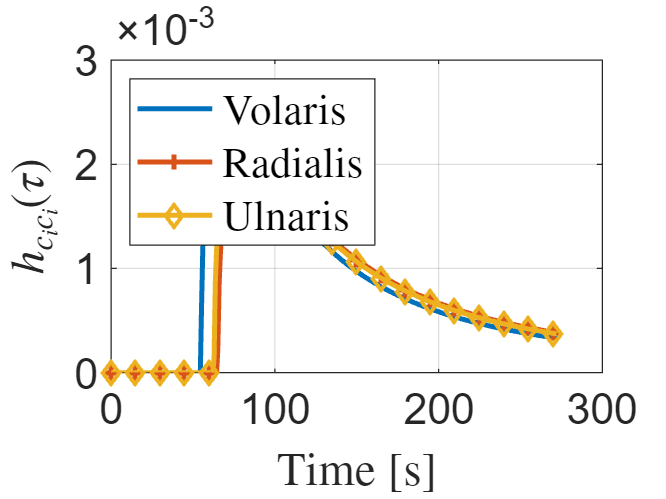



xlabel('Time [s]','Interpreter','latex');
ylabel('$h_{c_ic_i}(\tau)$','Interpreter','latex');
set(gca,'FontSize',fontsize);
% axis([0  0 200]);
grid on;

### Plotting Flow


st_point=100;

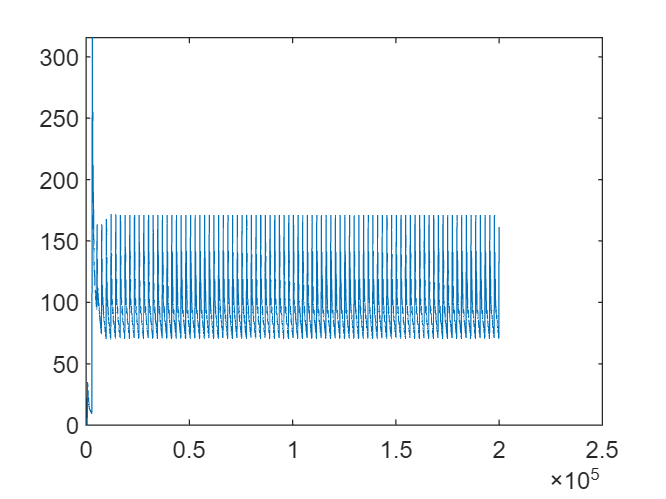

end_point=10*10^3;
time=(out_sim.P_AA.time(2)-out_sim.P_AA.time(1))*(0:end_point-st_point);
%setting to zero the negative out_simputs

figure;
plot(out_sim.P_TibPost.Data)

### Plotting Flow

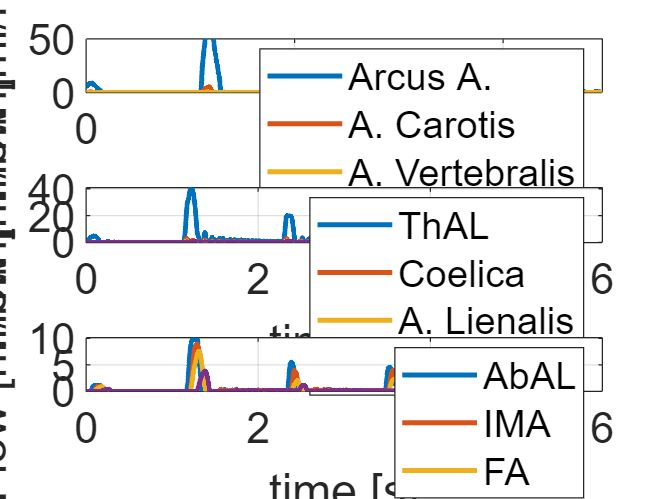

%Arms
F_SubC=(out_sim.F_SubC.data(st_point:end_point)+abs(out_sim.F_SubC.data(st_point:end_point)))/2;
F_SubC1=(out_sim.F_SubC1.data(st_point:end_point)+abs(out_sim.F_SubC1.data(st_point:end_point)))/2;
F_Brach=(out_sim.F_Brach.data(st_point:end_point)+abs(out_sim.F_Brach.data(st_point:end_point)))/2;
F_Brach1=(out_sim.F_Brach1.data(st_point:end_point)+abs(out_sim.F_Brach1.data(st_point:end_point)))/2;
F_Uln=(out_sim.F_Uln.data(st_point:end_point)+abs(out_sim.F_Uln.data(st_point:end_point)))/2;
F_Uln1=(out_sim.F_Uln1.data(st_point:end_point)+abs(out_sim.F_Uln1.data(st_point:end_point)))/2;
F_Anon=(out_sim.F_Anon.data(st_point:end_point)+abs(out_sim.F_Anon.data(st_point:end_point)))/2;
F_Anon1=(out_sim.F_Anon1.data(st_point:end_point)+abs(out_sim.F_Anon1.data(st_point:end_point)))/2;

%center body
F_Arcus=(out_sim.F_Arcus.data(st_point:end_point)+abs(out_sim.F_Arcus.data(st_point:end_point)))/2;
F_Arcus2=(out_sim.F_Arcus2.data(st_point:end_point)+abs(out_sim.F_Arcus2.data(st_point:end_point)))/2;
F_Arcus3=(out_sim.F_Arcus3.data(st_point:end_point)+abs(out_sim.F_Arcus3.data(st_point:end_point)))/2;
F_Arcus4=(out_sim.F_Arcus4.data(st_point:end_point)+abs(out_sim.F_Arcus4.data(st_point:end_point)))/2;
F_Arcus5=F_Arcus-F_Arcus2-F_Arcus3;
F_ThA=(out_sim.F_ThA.data(st_point:end_point)+abs(out_sim.F_ThA.data(st_point:end_point)))/2;

F_ThA1=(out_sim.F_ThA1.data(st_point:end_point)+abs(out_sim.F_ThA1.data(st_point:end_point)))/2;
F_Coel=F_ThA-F_ThA1;
F_Hep=(out_sim.F_Hep.data(st_point:end_point)+abs(out_sim.F_ThA1.data(st_point:end_point)))/2;
F_Lien=(out_sim.F_Lien.data(st_point:end_point)+abs(out_sim.F_Lien.data(st_point:end_point)))/2;
F_AbA=(out_sim.F_AbA.data(st_point:end_point)+abs(out_sim.F_AbA.data(st_point:end_point)))/2;
F_Rena=(out_sim.F_Rena.data(st_point:end_point)+abs(out_sim.F_Rena.data(st_point:end_point)))/2;
F_MesS=(out_sim.F_MesS.data(st_point:end_point)+abs(out_sim.F_MesS.data(st_point:end_point)))/2;
F_Rend=(out_sim.F_Rend.data(st_point:end_point)+abs(out_sim.F_Rend.data(st_point:end_point)))/2;
F_AbA1=(out_sim.F_AbA1.data(st_point:end_point)+abs(out_sim.F_AbA1.data(st_point:end_point)))/2;
F_MesI=(out_sim.F_MesI.data(st_point:end_point)+abs(out_sim.F_MesI.data(st_point:end_point)))/2;

%Legs
F_Legs=(out_sim.F_LegR.data(st_point:end_point)+out_sim.F_LegL.data(st_point:end_point)+abs(out_sim.F_LegL.data(st_point:end_point)+out_sim.F_LegR.data(st_point:end_point)))/2;
F_Fem=(out_sim.F_Fem.data(st_point:end_point)+abs(out_sim.F_Fem.data(st_point:end_point)))/2;
F_Fem1=(out_sim.F_Fem1.data(st_point:end_point)+abs(out_sim.F_Fem1.data(st_point:end_point)))/2;
F_Po=(out_sim.F_Po.data(st_point:end_point)+abs(out_sim.F_Po.data(st_point:end_point)))/2;
F_Po1=(out_sim.F_Po1.data(st_point:end_point)+abs(out_sim.F_Po1.data(st_point:end_point)))/2;

figure;
subplot 311
plot(time,100*F_Arcus,'LineWidth',line_width); hold on; grid on;
plot(time,100*(F_Arcus3-F_Arcus4),'LineWidth',line_width);
plot(time,100*(F_SubC-F_SubC1),'LineWidth',line_width);
ylabel('Flow [ml/min]');
set(gca,'FontSize',fontsize);
legend('Arcus A.','A. Carotis','A. Vertebralis');
axis([0 time(end) 0 50]);

subplot 312
plot(time,100*F_ThA,'LineWidth',line_width); hold on; grid on;
plot(time,100*F_Coel,'LineWidth',line_width);
plot(time,100*F_Lien,'LineWidth',line_width);
plot(time,100*F_Rena,'LineWidth',line_width);
ylabel('Flow [ml/min]');
xlabel('time [s]');
set(gca,'FontSize',fontsize);
legend('ThAL','Coelica','A. Lienalis','A. Renalis');
 
subplot 313
plot(time,100*F_Legs/2,'LineWidth',line_width); hold on; grid on;
plot(time,100*F_Fem,'LineWidth',line_width);
plot(time,100*F_Fem1,'LineWidth',line_width);
plot(time,100*F_Po,'LineWidth',line_width);
ylabel('Flow [ml/min]');
xlabel('time [s]');
set(gca,'FontSize',fontsize);
legend('AbAL','IMA','FA');

### Markov Model

#### Computing transition probabilities

Upper Body

p_LV_CenterBody=abs(F_Arcus2)./F_Arcus;
%setting to zero negative results
p_LV_CenterBody(find(~F_Arcus))=zeros(1,length(find(~F_Arcus)));
%setting to one larger probabilities
p_LV_CenterBody(find(p_LV_CenterBody>1))=ones(1,length(find(p_LV_CenterBody>1)));
P_LV_UpperBody=1-p_LV_CenterBody;
P_LV_UpperBody(find(~F_Arcus))=zeros(1,length(find(~F_Arcus)));


Arms

p_LV_SubC=abs(F_Arcus4)./F_Arcus3.*P_LV_UpperBody;
%setting to zero negative results
p_LV_SubC(find(~F_Arcus3))=zeros(1,length(find(~F_Arcus3)));
%setting to one larger probabilities
p_LV_SubC(find(p_LV_SubC>1))=ones(1,length(find(p_LV_SubC>1)));

P_Anon_SubC_d=(F_Anon-F_Anon1)./F_Anon;
%setting to zero negative results and NaN
P_Anon_SubC_d(find(P_Anon_SubC_d<0))=zeros(1,length(find(P_Anon_SubC_d<0)));
P_Anon_SubC_d(find(isnan(P_Anon_SubC_d)))=zeros(1,length(find(isnan(P_Anon_SubC_d))));
%setting to one larger probabilities
P_Anon_SubC_d(find(P_Anon_SubC_d>1))=ones(1,length(find(P_Anon_SubC_d>1)));

Head

p_LV_Carot_s=1-p_LV_SubC;
p_LV_Carot_s(find(~F_Arcus3))=zeros(1,length(find(~F_Arcus3)));
p_LV_Anon=(F_Arcus3-(F_Arcus-F_Arcus2))./(F_Arcus-F_Arcus2).*P_LV_UpperBody;
%setting to zero negative results and NaN
p_LV_Anon(find(p_LV_Anon<0))=zeros(1,length(find(p_LV_Anon<0)));
p_LV_Anon(find(isnan(p_LV_Anon)))=zeros(1,length(find(isnan(p_LV_Anon))));
%setting to one larger probabilities
p_LV_Anon(find(p_LV_Anon>1))=ones(1,length(find(p_LV_Anon>1)));

p_SubC_Axil=abs(F_SubC1)./F_SubC;
%setting to zero negative results
p_SubC_Axil(find(~F_SubC))=zeros(1,length(find(~F_SubC)));
%setting to one larger probabilities
p_SubC_Axil(find(p_SubC_Axil>1))=ones(1,length(find(p_SubC_Axil>1)));
p_SubC_Vert=1-p_SubC_Axil;
p_SubC_Vert(find(~F_SubC))=zeros(1,length(find(~F_SubC)));

p_Brach_Uln=abs(F_Brach1)./F_Brach;
%setting to zero negative results
p_Brach_Uln(find(~F_Brach))=zeros(1,length(find(~F_Brach)));
%setting to one larger probabilities
p_Brach_Uln(find(p_Brach_Uln>1))=ones(1,length(find(p_Brach_Uln>1)));
p_Brach_Rad=1-p_Brach_Uln;
p_Brach_Rad(find(~F_Brach))=zeros(1,length(find(~F_Brach)));

p_Brach_Uln2=abs(F_Uln1)./F_Uln.*p_Brach_Uln;
%setting to zero negative results
p_Brach_Uln2(find(~F_Uln))=zeros(1,length(find(~F_Uln)));
%setting to one larger probabilities
p_Brach_Uln2(find(p_Brach_Uln2>1))=ones(1,length(find(p_Brach_Uln2>1)));
p_Uln_Volaris=(1-p_Brach_Uln2).*p_Brach_Uln;
p_Uln_Volaris(find(~F_Uln))=zeros(1,length(find(~F_Uln)));

Center Body

p_ThA_AbA=abs(F_ThA1)./F_ThA.*p_LV_CenterBody;
%setting to zero negative results
p_ThA_AbA(find(~F_ThA))=zeros(1,length(find(~F_ThA)));
%setting to one larger probabilities
p_ThA_AbA(find(p_ThA_AbA>1))=ones(1,length(find(p_ThA_AbA>1)));
p_ThA_Coel=1-p_ThA_AbA;
p_ThA_Coel(find(~F_ThA))=zeros(1,length(find(~F_ThA)));

p_Coel_Hep=abs(F_Hep)./F_Coel;
%setting to zero negative results and NaN
p_Coel_Hep(find(p_Coel_Hep<0))=zeros(1,length(find(p_Coel_Hep<0)));
p_Coel_Hep(find(~F_Coel))=zeros(1,length(find(~F_Coel)));
%setting to one larger probabilities
p_Coel_Hep(find(p_Coel_Hep>1))=ones(1,length(find(p_Coel_Hep>1)));

p_Coel_Lien=abs(F_Lien)./F_Coel;
%setting to zero negative results and NaN
p_Coel_Lien(find(p_Coel_Lien<0))=zeros(1,length(find(p_Coel_Lien<0)));
p_Coel_Lien(find(~F_Coel))=zeros(1,length(find(~F_Coel)));
%setting to one larger probabilities
p_Coel_Lien(find(p_Coel_Lien>1))=ones(1,length(find(p_Coel_Lien>1)));

p_Coel_Gast=1-p_Coel_Hep-p_Coel_Lien;
p_Coel_Gast(find(p_Coel_Gast<0))=zeros(1,length(find(p_Coel_Gast<0)));

p_AbA_MesS=abs(F_MesS)./F_AbA;
%setting to zero negative results
p_AbA_MesS(find(~F_AbA))=zeros(1,length(find(~F_AbA)));
%setting to one larger probabilities
p_AbA_MesS(find(p_AbA_MesS>1))=ones(1,length(find(p_AbA_MesS>1)));

p_AbA_Rend=abs(F_Rend)./F_AbA;
%setting to zero negative results
p_AbA_Rend(find(~F_AbA))=zeros(1,length(find(~F_AbA)));
%setting to one larger probabilities
p_AbA_Rend(find(p_AbA_Rend>1))=ones(1,length(find(p_AbA_Rend>1)));

p_AbA_Rens=abs(F_Rena)./F_AbA;
%setting to zero negative results
p_AbA_Rens(find(~F_AbA))=zeros(1,length(find(~F_AbA)));
%setting to one larger probabilities
p_AbA_Rens(find(p_AbA_Rens>1))=ones(1,length(find(p_AbA_Rens>1)));

p_Kidneys=p_AbA_Rend+p_AbA_Rens;
p_Kidneys(find(p_Kidneys>1))=ones(1,length(find(p_Kidneys>1)));

Lower Body

p_AbA_Leg_L=1/2*abs(F_Legs)./F_AbA1.*(1-p_AbA_Rend-p_AbA_MesS-p_AbA_Rens);
%setting to zero negative results and NaN
p_AbA_Leg_L(find(~F_AbA1))=zeros(1,length(find(~F_AbA1)));
p_AbA_Leg_L(find(p_AbA_Leg_L<0))=zeros(1,length(find(p_AbA_Leg_L<0)));
%setting to one larger probabilities
p_AbA_Leg_L(find(p_AbA_Leg_L>1))=ones(1,length(find(p_AbA_Leg_L>1)));
p_AbA_MesI=1-2*p_AbA_Leg_L-p_AbA_Rend-p_AbA_MesS-p_AbA_Rens;
%setting to zero negative results
p_AbA_MesI(find(p_AbA_MesI<0))=zeros(1,length(find(p_AbA_MesI<0)));

p_Fem_Po=abs(F_Fem1)./F_Fem;
%setting to zero negative results
p_Fem_Po(find(~F_Fem))=zeros(1,length(find(~F_Fem)));
%setting to one larger probabilities
p_Fem_Po(find(p_Fem_Po>1))=ones(1,length(find(p_Fem_Po>1)));
p_Fem_ProfF=1-p_Fem_Po;
p_Fem_ProfF(find(~F_Fem))=zeros(1,length(find(~F_Fem)));

p_Fem_TibP=abs(F_Po1)./F_Po;
%setting to zero negative results
p_Fem_TibP(find(~F_Po))=zeros(1,length(find(~F_Po)));
%setting to one larger probabilities
p_Fem_TibP(find(p_Fem_TibP>1))=ones(1,length(find(p_Fem_TibP>1)));
p_Fem_TibA=1-p_Fem_TibP;
p_Fem_TibA(find(~F_Po))=zeros(1,length(find(~F_Po)));


Plotting transition probabilities

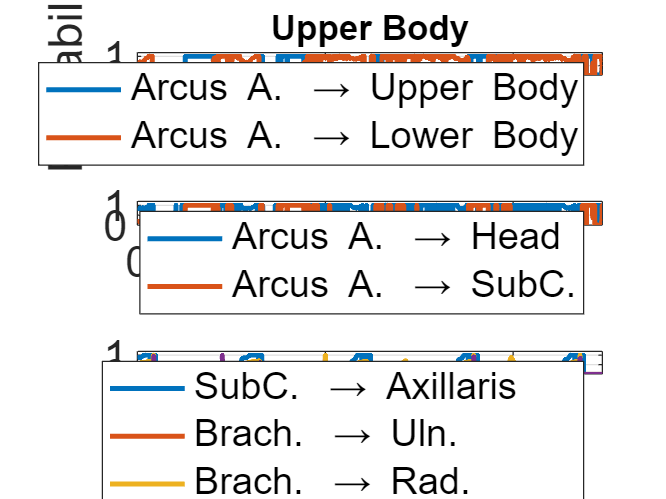

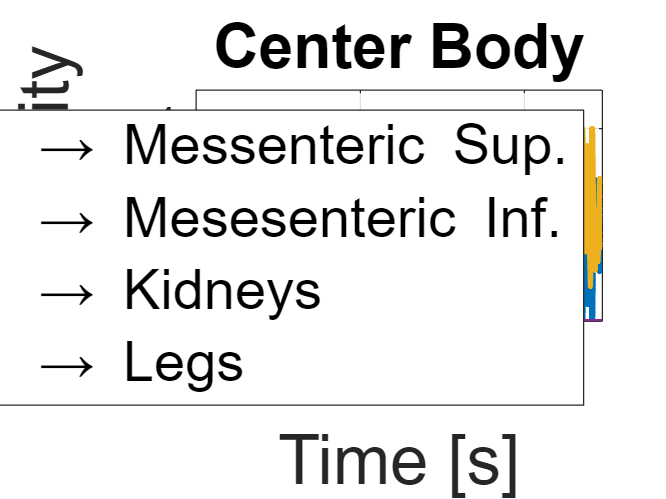

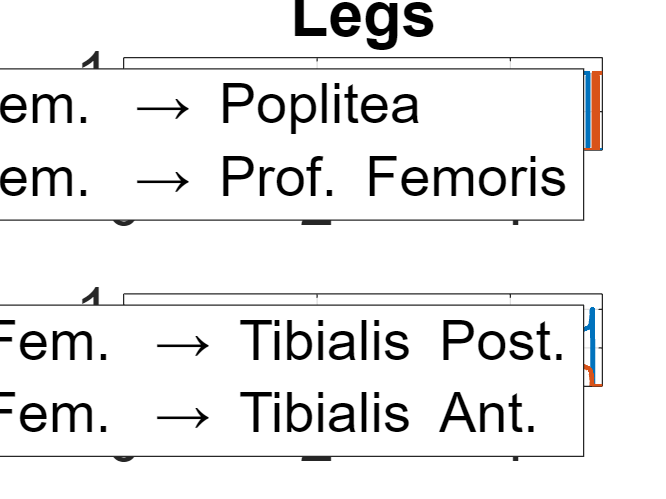

plot_transition_prob

### Transition matrix per segment

The calculated transition matrix follows the step visualized in Fig. 3

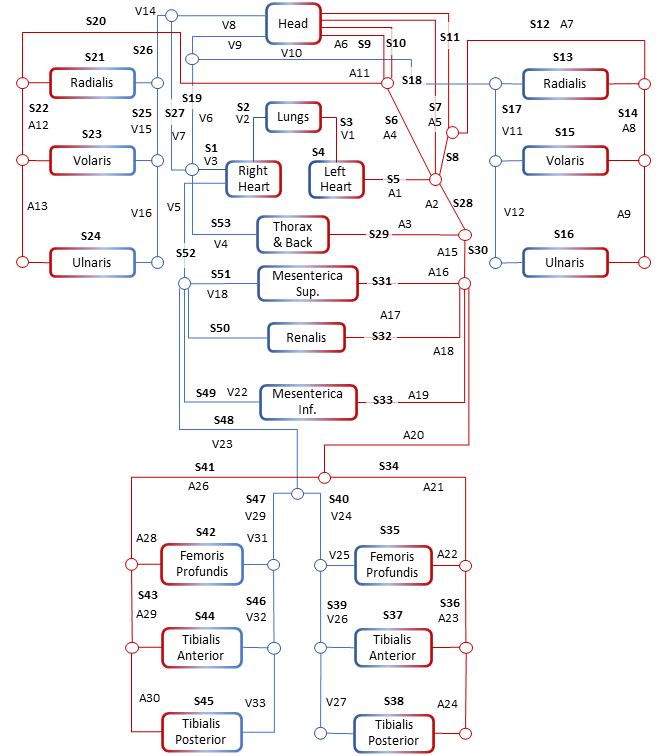

Figure 3: Markov model states.


PI=zeros(53,53);

%Upper Body
PI(1,2)=1;
PI(2,3)=1;
PI(3,4)=1;
PI(4,5)=1;


Head

% Arcus Aorta -> Thorax Aorta
% RLC_3 -> RLC_4
PI(5,28)=mean(F_Arcus2)/mean(F_Arcus);
% Arcus Aorta -> Anonima
% RLC_3 -> RLC_91
PI(5,6)=1-PI(5,28)-abs(mean(F_Arcus3))/mean(F_Arcus);   
% Arcus Aorta -> Carotis Comunis s.
% RLC_3 -> RLC_97
PI(5,7)=abs(mean(F_Arcus4-F_Arcus3))/mean(F_Arcus);
% Arcus Aorta -> SubClavia s.
% RLC_3 -> RLC_71
PI(5,8)=abs(mean(F_Arcus4))/mean(F_Arcus);
% Subclavia s. -> Vertebralis s.
% RLC_71 -> RLC_83
PI(8,11)=1-mean(abs(F_SubC1))./mean(F_SubC);
% Anonima -> Carotis Comunis d.
% RLC_91->RLC_103
PI(6,10)=PI(5,7);
% Anonima -> Vertebralis d.
% RLC_91->RLC_106
PI(6,9)=PI(8,11);
%Veins
%Carotis and Vertabralis d. are connected to S27
PI(9,19)=1;
PI(10,19)=1;
%Carotis and Vertabralis s. are connected to S19
PI(7,27)=1;
PI(11,27)=1;


Left Arm

%Arteries
% Subclavia -> Axillaris s.
% RLC_71 -> RLC_72
PI(8,12)=1-PI(8,11);
% Brachialis -> Radialis s
% RLC_78 -> RLC_85
PI(12,13)=1-mean(F_Brach1)./mean(F_Brach);
% Brachialis -> Ulnaris s. 1
% RLC_78 -> RLC_79
PI(12,14)=mean(F_Brach1)./mean(F_Brach);
% Ulnaris s. 1 -> Volaris s
% RLC_79 -> RLC_89
PI(14,15)=1-mean(F_Uln1)./mean(F_Uln);
% Ulnaris s. 1 -> Ulnaris s
% RLC_79 -> RLC_80
PI(14,16)=mean(F_Uln1)./mean(F_Uln);
%Veins
PI(13,18)=1;
PI(17,18)=1;
PI(15,17)=1;
PI(16,17)=1;
PI(18,19)=1;
PI(19,1)=1;


Right Arm

%Arteries
% Anonima -> Subclavia d.
% RLC_91 -> RLC_92
PI(6,20)=1-PI(6,9)-PI(6,10);
% Brachialis d. -> Radialis d.
% RLC_98 -> RLC_108
PI(20,21)=PI(12,13);
% Brachialis d. -> Ulnaris d. 1
% RLC_98 -> RLC_99
PI(20,22)=PI(12,14);
% Ulnaris d. 1 -> Volaris d.
% RLC_99 -> RLC_112
PI(22,23)=PI(14,15);
% Ulnaris d. 1 -> Ulnaris d.
% RLC_99 -> RLC_100
PI(22,24)=PI(14,16);
%Veins
PI(21,26)=1;
PI(23,25)=1;
PI(24,25)=1;
PI(25,26)=1;
PI(26,27)=1;
PI(27,1)=1;

Center Body

% Thorax A. -> Coelica
% RLC_7 -> RLC_63
PI(28,29)=1-mean(F_ThA1)./mean(F_ThA);
% Thorax A. -> Abdominalis
% RLC_7 -> RLC_8
PI(28,30)=1-PI(28,29);
% Abdominalis -> Mesenterica Sup.
% RLC_8 -> RLC_61
PI(30,31)=mean(F_MesS)./mean(F_AbA);
% Abdominalis -> Renalis
% RLC_8 -> RLC_60
PI(30,32)=2*mean(F_Rena)./mean(F_AbA);
% Abdominalis -> Mesenterica Inf.
% RLC_10 -> RLC_35 
PI(30,33)=mean(F_MesI)./mean(F_AbA1);
%Veins
PI(29,53)=1;
PI(31,51)=1;
PI(32,50)=1;
PI(33,49)=1;
PI(48,52)=1;
PI(49,52)=1;
PI(50,52)=1;
PI(51,52)=1;
PI(53,1)=1;
PI(52,1)=1;

Left Leg

% Abdominalis -> Iliaca Communis s.
% RLC_10 -> RLC_11 
PI(30,34)=1/2*(1-(PI(30,31)+PI(30,32)+PI(30,33)));
% Femoralis s. 1 -> Profundis Femoris s.
% RLC_14 -> RLC_27
PI(34,35)=1-mean(F_Fem1)./mean(F_Fem);
% Femoralis s. 1 -> Femoralis s.
% RLC_14 -> RLC_27
PI(34,36)=1-PI(34,35);
% Poplitea s. -> Tibialis Anterior s.
% RLC_21 -> RLC_30
PI(36,37)=1-mean(F_Po1)./mean(F_Po);
% Poplitea s. -> Tibialis Anterior s.
% RLC_21 -> RLC_22
PI(36,38)=1-PI(36,37);
%Veins
PI(38,39)=1;
PI(37,39)=1;
PI(38,39)=1;
PI(39,40)=1;
PI(35,40)=1;
PI(40,48)=1;

Right Leg

% Abdominalis -> Iliaca Communis s.
% RLC_10 -> RLC_11 
PI(30,41)=PI(30,34);
% Femoralis s. 1 -> Profundis Femoris s.
% RLC_14 -> RLC_27
PI(41,42)=PI(34,35);
% Femoralis s. 1 -> Femoralis s.
% RLC_14 -> RLC_27
PI(41,43)=PI(34,36);
% Poplitea s. -> Tibialis Anterior s.
% RLC_21 -> RLC_30
PI(43,44)=PI(36,37);
% Poplitea s. -> Tibialis Anterior s.
% RLC_21 -> RLC_22
PI(43,45)=PI(36,38);
%Veins
PI(45,46)=1;
PI(44,46)=1;
PI(38,39)=1;
PI(42,47)=1;
PI(46,47)=1;
PI(47,48)=1;

Calculating the Markov Model

mc = dtmc(PI);
% figure;
% graphplot(mc);
xFix = asymptotics(mc);
%validating
sum(xFix)

ans = 1

#### Markov Model per circuit

This model evaluates the transition probabilites per circuit, as depicted in the Fig. 2

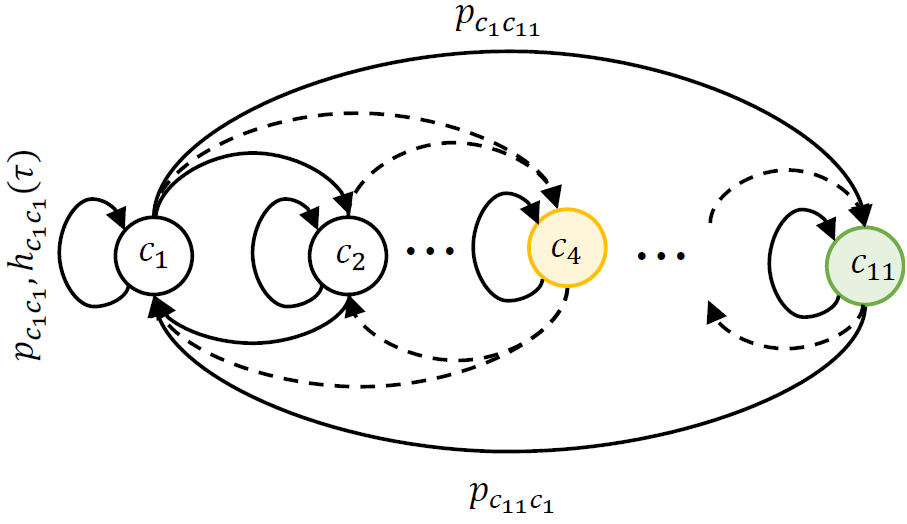

Figure 2: Markov model per circuit.

where each circuit follows the labeling

total_circuits=11;
%labeling the circuits in the HCS
circuits_tissues={...%upper body
                  'Head', ...% -> c1
                  'Radialis',...% -> c2
                  'Volaris',...% -> c3
                  'Ulnaris', ...% -> c4
                  ...%Center Body
                  'Thorax',...% -> c5
                  'Mesentrica Superior', ...% -> c6
                  'Mesenterica Inferior',...% -> c7
		          'Renalis',...% -> c8
                  ...%Lower Body
                  'Femoralis Profundis',...% -> c9
                  'Tibialis Anterior',...% -> c10
                  'Tibialis Posterior'};% -> c11

#### Computing the probabilities along circuits

PI_circuits=zeros(11,11);%transition matrix

Head ($c_1$)

%Head -> Head
PI_circuits(1,1)=PI(5,6)*(PI(6,9)+PI(6,10))+PI(5,7)+PI(5,8)*PI(8,11);
%Head -> Radialis
PI_circuits(1,2)=PI(5,8)*PI(8,12)*PI(12,13)+PI(5,6)*PI(6,20)*PI(20,21);
%Head -> Volaris
PI_circuits(1,3)=PI(5,8)*PI(8,12)*PI(12,14)*PI(14,15)+PI(5,6)*PI(6,20)*PI(20,22)*PI(22,23);
%Head -> Ulnaris
PI_circuits(1,4)=PI(5,8)*PI(8,12)*PI(12,14)*PI(14,16)+PI(5,6)*PI(6,20)*PI(20,22)*PI(22,24);
%Head -> Thorax
PI_circuits(1,5)=PI(5,28)*PI(28,29);
%Head -> Mesenterica Sup
PI_circuits(1,6)=PI(5,28)*PI(28,30)*PI(30,31);
%Head -> Renalis
PI_circuits(1,7)=PI(5,28)*PI(28,30)*PI(30,32);
%Head -> Mesenterica Inf.
PI_circuits(1,8)=PI(5,28)*PI(28,30)*PI(30,33);
%Head -> Femoris Profundis
PI_circuits(1,9)=2*PI(5,28)*PI(28,30)*PI(30,34)*PI(34,35);
%Head -> Tibialis Anterior
PI_circuits(1,10)=2*PI(5,28)*PI(28,30)*PI(30,34)*PI(34,36)*PI(36,37);
%Head -> Tibialis Posterior
PI_circuits(1,11)=2*PI(5,28)*PI(28,30)*PI(30,34)*PI(34,36)*PI(36,38);

For the remanent circuits the transition probabilities is a copy of the row PI(1,:)

for i=2:total_circuits
    PI_circuits(i,:)=PI_circuits(1,:);
end

prob_circuit=[PI_circuits(1,1),PI_circuits(2,2),PI_circuits(3,3),PI_circuits(4,4), ...%upper body
              PI_circuits(5,5),PI_circuits(6,6),PI_circuits(7,7),PI_circuits(8,8), ...% center body
              PI_circuits(9,9),PI_circuits(10,10),PI_circuits(11,11)];%lower body

%validating
sum(prob_circuit)

ans = 1

Calculating the Markov Model

mc = dtmc(PI_circuits);
% figure;
% graphplot(mc);
xFix_circuits = asymptotics(mc);
%validating
sum(xFix_circuits)

ans = 1.0000

#### Evaluating the holding time sequence


$$h_{c_i}(\tau)=\frac{l_{c_i}}{2v_c\tau^2\sqrt{1-\frac{T_{c_i}}{\tau}}}u\left(\tau-T_{c_i}\right),\quad i\in\{4,11\}$$


figure;
time=0:sample_time:4*max(circuit_time_min);
jump=1;
k=1;
for i=[2 3 4]
    t1=find(time>=circuit_length(i)/circuit_speed(i),1);
    plot(time,...
         horzcat(zeros(1,t1-1),...
         circuit_length(i)./(2*circuit_speed(i)*time(t1:end).^2).*sqrt(1-t1*sample_time./time(t1:end))),...
         marker{k},'LineWidth',line_width,'Color',color{k},...
         'MarkerIndices',1:3*10^4:numel(time)); hold on;
    k=k+1;
end

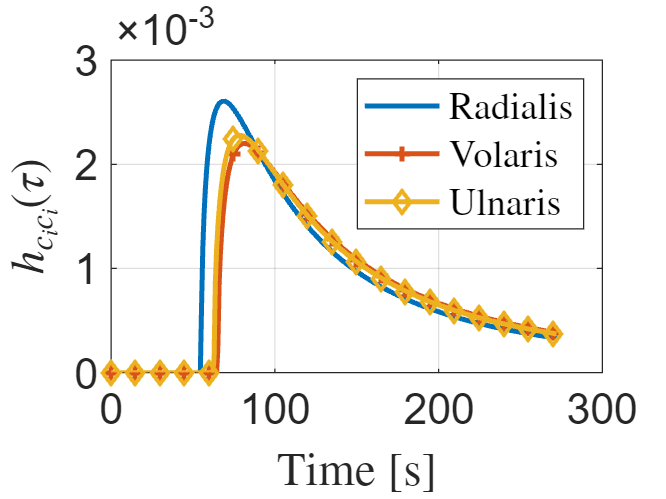

grid on;
xlabel('Time [s]','Interpreter','latex');
ylabel('$h_{c_ic_i}(\tau)$','Interpreter','latex');
legend({'Radialis','Volaris','Ulnaris'},'Interpreter','latex');
set(gca,'Fontsize',fontsize);

#### Evaluating the conditional transition probability

$p_{c_ic_j}(t)=\frac{p_{c_ic_j}h_{c_ic_j}(t)}{w_{c_i}(t)}$ [4, Eq. (11.6.2) pp. 715]

where

$ w_{c_i}(t) =p_{c_ic_i}h_{c_ic_i}(t),$ [4, Eq. (11.1.4) pp. 691]

Evaluating $c_{11}$ to $c_4$

time=0:sample_time:100*max(circuit_time_min);
H=zeros(11,length(time));
for i=1:11
    t1=find(time>=circuit_time_min(i),1);
    H(i,:)=horzcat(zeros(1,t1-1),...
            circuit_length(4)./(2*circuit_speed(i)*time(t1:end).^2).*sqrt(1-t1*sample_time./time(t1:end)));
end

W=zeros(11,length(time));
for i=1:11
    for j=1:11
        W(i,:)=W(i,:)+PI_circuits(i,j)*H(j,:);
    end
end



figure;
%p_c11c4
n_end=length(phi_c11c4);
t1=find(time>=circuit_time_min(4)/2,1);
t2=find(time>=circuit_time_min(11)/2,1);
p_c11c4=horzcat(zeros(1,t1+t2-1),PI_circuits(11,4)*H(4,t1:end)./W(4,t1:end));
p_c11c11=horzcat(zeros(1,t2-1),PI_circuits(11,11)*H(11,t1:end)./W(4,t1:end));
plot((0:length(p_c11c4)-1)*sample_time,p_c11c4,'LineWidth',2); hold on; grid on;

ans = 0.0980

ans = 0.3966

plot((0:length(p_c11c11)-1)*sample_time,p_c11c11,'--','LineWidth',2);

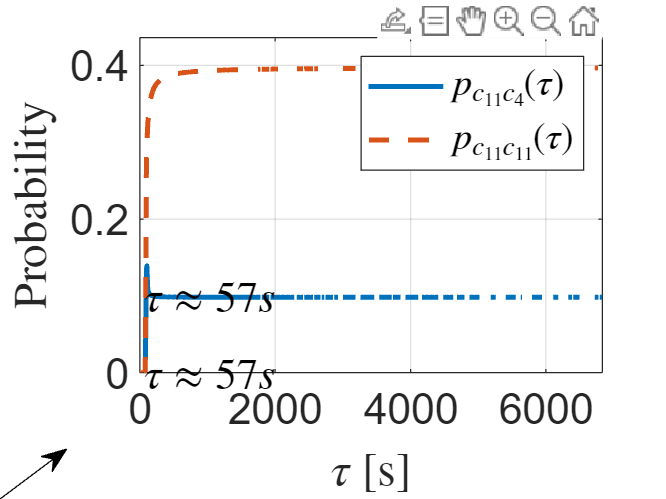

xlabel('$\tau$ [s]','Interpreter','latex');
ylabel('Probability','Interpreter','latex');
legend({'$p_{c_{11}c_4}(\tau)$','$p_{c_{11}c_{11}}(\tau)$'},'Interpreter','latex');
annotation('arrow',[0 0.1],[0 0.1]);
text([0 0.1],[0 0.1],strcat('$\tau\approx',num2str((t1+t2)*sample_time,2),' s$'),'FontSize',fontsize,'Interpreter','latex');

set(gca,'Fontsize',fontsize);
axis([0 (length(p_c11c4)-1)*sample_time 0 1.1*max([p_c11c4 p_c11c11])]);


Calculating the 

Calculating the average time


$$T_{c_{4}}=\int_0^{\infty}{\tau\, h_{c_4c_4}(\tau)d\tau},$$



T_c4=trapz(time.*real(H(4,:)))*sample_time

T_c4 = 138.4437

Calculating the average rate for the number of nanosensors

$\lambda=\frac{N_{c_{11}c_4}}{T_{c_{4}}}$,

where


$$N_{c_{11}c_4}=N\times\lim_{t\rightarrow \infty}p_{c_{11}c_4}(t)p_{c_{11}c_{11}}(t)$$


and $N={10}^6$ is the total of nanosensors in the system

N=10^5;
lambda=N*p_c11c4(end)*p_c11c11(end)/T_c4

lambda = 28.0843

### Plotting the probability for nanosensors to travel along circuits and the traveling time

fontsize=17;
font2=17;
y_lim=0.3;
width=0.5;

figure;

%probability bars
p=bar((1:2:2*length(prob_circuit)),prob_circuit,width,'LineWidth',1.5,'LineStyle','-','FaceColor','#77AC30','EdgeColor','#77AC30'); hold off
set(p,'FaceAlpha',0.5);
ylabel('Probability');
axis([0.5 2*length(prob_circuit)+1 0 0.3]);
set(gca,'FontSize',fontsize,'YColor','#77AC30');

yyaxis right
%traveling time bars
p=bar(2:2:2*length(prob_circuit),circuit_time_min,width,'LineWidth',1.5,'LineStyle','-','FaceColor','#EDB120','EdgeColor','#EDB120'); hold on
set(p,'FaceAlpha',0.5);
ylabel('Traveling time [s]');
set(gca,'FontSize',fontsize,'YColor','#EDB120');

set(gca, 'XTick', [1.5:2:2*length(prob_circuit)]);
set(gca, 'XTickLabel', {'Head','Radialis','Volaris','Ulnaris',...
    'Thorax','Mesenteric Sup.','Mesenteric Inf.','Kidneys',...
    'Femoralis Prof.','Tibialis A.','Tibialis P.'});
xtickangle(45);
grid on;

%text
y_txt=0.15;
ht=text(2.5, y_txt,{'Upper Body'},'FontSize',font2);
set(ht,'Rotation',90);
ht=text(13, y_txt,{'Center Body'},'FontSize',font2);
set(ht,'Rotation',90);
ht=text(20, y_txt,{'Lower Body'},'FontSize',font2);
set(ht,'Rotation',90);

%patchs
%Upper body
p=patch([0.5 2*4+0.5 2*4+0.5 0.5],[0 0 1.1*max(circuit_time_min) 1.1*max(circuit_time_min)],[0.3010 0.7450 0.9330],"EdgeColor",'black','LineWidth',1);hold on;
set(p,'FaceAlpha',0);
%Lower body
p=patch([16.5 22.5 22.5 16.5],[0 0 1.1*max(circuit_time_min) 1.1*max(circuit_time_min)],[0.3010 0.7450 0.9330],"EdgeColor",'black','LineWidth',1);
set(p,'FaceAlpha',0);

axis([0.5 2*length(prob_circuit)+0.5 0 1.1*max(circuit_time_min)]);

## Plotting the stationary distribution of nanosensors

fontsize=17;
font2=17;
width=1;

%static

% xFix=xFix_static;
xFix_static=xFix;
arteries_bar=[ xFix_static(5),xFix_static(6),xFix_static(8),xFix_static(9),xFix_static(10),... %Upper Body
               xFix_static(29),xFix_static(31),... %center body              
               xFix_static(38),xFix_static(40)];%legs
x_artieries=1:length(arteries_bar);
capillaries_bar=[xFix_static(1),xFix_static(2),xFix_static(3),xFix_static(30),xFix_static(32),xFix_static(33),xFix_static(34),xFix_static(35),... %center body
              xFix_static(7),xFix_static(11),xFix_static(12),xFix_static(13),... %arms
              xFix_static(39),xFix_static(41),xFix_static(42)];%legs
x_capillaries=x_artieries(end)+(1:length(capillaries_bar));
veins_bar=[xFix_static(28),xFix_static(26),xFix_static(27),... %Upper body
           xFix_static(37),xFix_static(36),... %center body
           xFix_static(43),xFix_static(44)];%legs
x_veins=x_capillaries(end)+(1:length(veins_bar));



figure;
y_lim=0.12;
%patchs
%arteries center body
p=patch([0.5 5.5 5.5 0.5],[0 0 y_lim y_lim],[0.3010 0.7450 0.9330],"EdgeColor",'#0072BD');hold on;
set(p,'FaceAlpha',0.5);
%arteries legs
p=patch([7.5 9.5 9.5 7.5],[0 0 y_lim y_lim],[0.3010 0.7450 0.9330],"EdgeColor",'#0072BD');hold on;
set(p,'FaceAlpha',0.5);
%capillaries Upper body
p=patch([x_capillaries(1)+7.5 x_capillaries(1)+11.5 x_capillaries(1)+11.5 x_capillaries(1)+7.5],[0 0 y_lim y_lim],[0.3010 0.7450 0.9330],"EdgeColor",'#0072BD');hold on;
set(p,'FaceAlpha',0.5);
%veins Upper body
p=patch([x_veins(1)-.5 x_veins(1)+2.5 x_veins(1)+2.5 x_veins(1)-.5],[0 0 y_lim y_lim],[0.3010 0.7450 0.9330],"EdgeColor",'#0072BD');hold on;
set(p,'FaceAlpha',0.5);
%veins legs
p=patch([x_veins(1)+5-.5 x_veins(end)+.5 x_veins(end)+.5 x_veins(1)+5-.5],[0 0 y_lim y_lim],[0.3010 0.7450 0.9330],"EdgeColor",'#0072BD');hold on;
set(p,'FaceAlpha',0.5);

%arteries
h_arteries=bar(x_artieries,arteries_bar,width,'LineWidth',1.5,'LineStyle','--','FaceColor','#D95319','EdgeColor','#000000'); 
set(h_arteries,'FaceAlpha',0.5);
%capillaries
h_capillaries=bar(x_capillaries,capillaries_bar,width,'LineWidth',1.5,'LineStyle','--','FaceColor','#77AC30','EdgeColor','#000000');
set(h_capillaries,'FaceAlpha',0.5);
%veins
h_veins=bar(x_veins,veins_bar,width,'LineWidth',1.5,'LineStyle','--','FaceColor','#0072BD','EdgeColor','#000000'); 
set(h_veins,'FaceAlpha',0.5);

%ytickangle(90);
% new = copyobj(gca,gcf);
% set(new,'YAxisLocation','right');

%in the case you plot for two activity regimes
xFix_dyn=xFix;

arteries_bar=[ xFix_dyn(5),xFix_dyn(6),xFix_dyn(8),xFix_dyn(9),xFix_dyn(10),... %Upper Body
               xFix_dyn(29),xFix_dyn(31),... %center body              
               xFix_dyn(38),xFix_dyn(40)];%legs
x_artieries=1:length(arteries_bar);
capillaries_bar=[xFix_dyn(1),xFix_dyn(2),xFix_dyn(3),xFix_dyn(30),xFix_dyn(32),xFix_dyn(33),xFix_dyn(34),xFix_dyn(35),... %center body
              xFix_dyn(7),xFix_dyn(11),xFix_dyn(12),xFix_dyn(13),... %arms
              xFix_dyn(39),xFix_dyn(41),xFix_dyn(42)];%legs
x_capillaries=x_artieries(end)+(1:length(capillaries_bar));
veins_bar=[xFix_dyn(28),xFix_dyn(26),xFix_dyn(27),... %Upper body
           xFix_dyn(37),xFix_dyn(36),... %center body
           xFix_dyn(43),xFix_dyn(44)];%legs
x_veins=x_capillaries(end)+(1:length(veins_bar));



%arteries
h_arteries=bar(x_artieries,arteries_bar,width,'LineWidth',1.5,'FaceColor','#D95319','EdgeColor','#000000'); 
set(h_arteries,'FaceAlpha',0.5);
%capillaries
h_capillaries=bar(x_capillaries,capillaries_bar,width,'LineWidth',1.5,'FaceColor','#77AC30','EdgeColor','#000000');
set(h_capillaries,'FaceAlpha',0.5);
%veins
h_veins=bar(x_veins,veins_bar,width,'LineWidth',1.5,'FaceColor','#0072BD','EdgeColor','#000000'); 
set(h_veins,'FaceAlpha',0.5);
%text
y_txt=0.04;
ht=text(2.5, y_txt+0.01,{'Arteries Upper Body'},'FontSize',font2);
set(ht,'Rotation',90);
ht=text(6, y_txt,{'Arteries Center Body'},'FontSize',font2);
set(ht,'Rotation',90);
ht=text(8.2, y_txt-0.02,{'Arteries Legs'},'FontSize',font2);
set(ht,'Rotation',90);
ht=text(13.5, y_txt-0.02,{'Capillaries Upper Body'},'FontSize',font2);
set(ht,'Rotation',90);
ht=text(19.5, y_txt-0.02,{'Capillaries Center Body'},'FontSize',font2);
set(ht,'Rotation',90);
ht=text(23, y_txt-0.02,{'Capillaries Legs'},'FontSize',font2);
set(ht,'Rotation',90);
ht=text(26, y_txt+0.01,{'Veins Upper Body'},'FontSize',font2);
set(ht,'Rotation',90);
ht=text(28.5, y_txt-0.02,{'Veins Center','Body'},'FontSize',font2);
set(ht,'Rotation',90);
ht=text(30.5, y_txt-0.02,{'Veins Legs'},'FontSize',font2);
set(ht,'Rotation',90);

set(gca, 'XTick', [1:length(arteries_bar)+length(capillaries_bar)+length(veins_bar)]);
set(gca, 'XTickLabel', {'Arcus. A','A. Anonyma','A. Subclavia s.','A. Axillaris s.','A. Brachialis s.',...
    'Thoratica A.','Abdominal A.','A. Iliaca Comm. s.','A. Poplitea s.'...
    'R. Heart','Lungs','L. Heart','Thorax','Mesenteric Sup.','Mesenteric Inf.','Liver','Kidneys',...
    'Head','Radialis s.','Volaris s.','Ulnaris s.',...
    'Femoralis Prof.','Tibialis A.','Tibialis P.',...
    'Sup. Vena Cava','Jugular Vein','Subclavia d.',...
    'Inf. Vena Cava','Abdominal V.',...
    'V. Poplitea s.','V. Iliaca Comm. s.'});

grid on;
axis([0.5 x_veins(end)+.5 0 y_lim]);
set(gca,'FontSize',fontsize);
xtickangle(90);
ylabel('Stationary probability');

### References

[1] H. C. Berg, Random Walks in Biology. Princeton University Press, 1993.

[2] A. Noordergraaf, P. D. Verdouw, and H. B. Boom, “The use of an analog computer in a circulation model,” Progress in Cardiovascular Diseases, vol. 5, no. 5, pp. 419–439, Mar. 1963.

[3] N. Westerhof, F. Bosman, C. J. D. Vries, and A. Noordergraaf, “Analog studies of the human systemic arterial tree,” Journal of Biomechanics, vol. 2, no. 2, pp. 121–143, May 1969

[4] R. A. Howard, Dynamic probabilistic systems. Wiley, 1971, vol. II, p. 1107.